# TP1 multicrit

## parameters

variables : r  and  l

interval : r et l respectively: [0.04, 0.08],[10,40]           [0.04,0.08,10,40]

h=20;
k=1.4;
ri=0.03;
Rth= @(r,l) 1/(2*pi*h*r*l)+log(r/ri)/(2*pi*k*l)

Rth = function_handle with value:
    @(r,l)1/(2*pi*h*r*l)+log(r/ri)/(2*pi*k*l)


## Decision variable

step_r=0.001;
step_l=1;
r=0.04:step_r:0.08;
l=10:step_l:40;

## Q1 min Rth (feat optimization toolbox) (not succeed)

figure(1)
fsurf(Rth,[0.04,0.08,10,40])

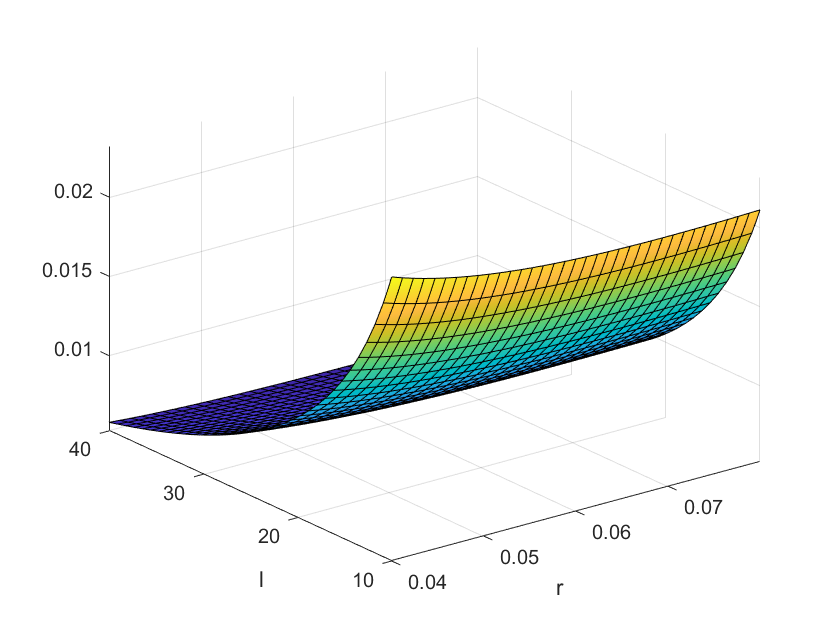

xlabel('r')
ylabel('l')


% fun = @(r) Rth(r(1),r(2));
r0 = [0.4; 0.07];
options = optimoptions('fminunc','Algorithm','quasi-newton');
options.Display = 'iter';
[r, fval, exitflag, output] = fminunc(Rth,r0,options);

Not enough input arguments.

Error in multicrit_tp1 (line 4)
Rth= @(r,l) 1/(2*pi*h*r*l)+log(r/ri)/(2*pi*k*l)

Error in fminunc (line 304)
        f = feval(funfcn{3},x,varargin{:});

Caused by:
    Failure in initial objective function evaluation. FMINUNC cannot continue.

## Q1 min Rth (discrétiser) (objective space)

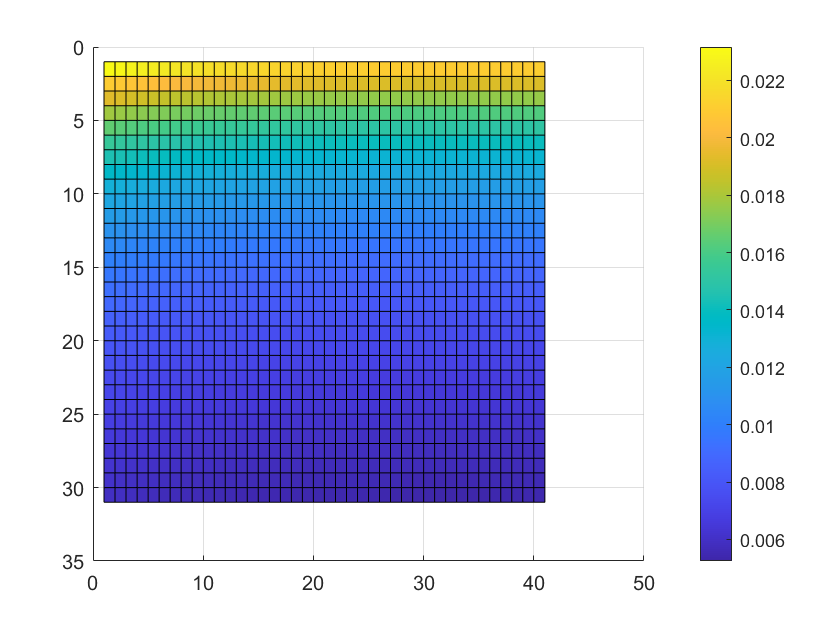

Rth_matrix=zeros(length(r),length(l));
for i=1:length(r)
    for j=1:length(l)
        Rth_matrix(i,j)=1/(2*pi*h*r(i)*l(j))+log(r(i)/ri)/(2*pi*k*l(j));
    end
end
% Rth_matrix
surf(Rth_matrix)
view([90,90])
colorbar

min_Rth=min(min(Rth_matrix))

min_Rth = 0.0053

[irow jcol]= find(Rth_matrix ==min_Rth) %it gives the linear index

irow = 31

jcol = 31

r_min_Rth=r(irow)

r_min_Rth = 0.0700

l_min_Rth=l(jcol)

l_min_Rth = 40

## Q2 min volume (discrétiser) (objective space)

V_matrix=zeros(length(r),length(l));
for i=1:length(r)
    for j=1:length(l)
        V_matrix(i,j)=pi*(r(i)^2-ri^2)*l(j);
    end
end
V_matrix

V_matrix =     0.0220    0.0242    0.0264    0.0286    0.0308    0.0330    0.0352    0.0374    0.0396    0.0418    0.0440    0.0462    0.0484    0.0506    0.0528    0.0550    0.0572    0.0594    0.0616    0.0638    0.0660    0.0682    0.0704    0.0726    0.0748    0.0770    0.0792    0.0814    0.0836    0.0858    0.0880
    0.0245    0.0270    0.0294    0.0319    0.0344    0.0368    0.0393    0.0417    0.0442    0.0466    0.0491    0.0515    0.0540    0.0564    0.0589    0.0613    0.0638    0.0662    0.0687    0.0712    0.0736    0.0761    0.0785    0.0810    0.0834    0.0859    0.0883    0.0908    0.0932    0.0957    0.0981
    0.0271    0.0299    0.0326    0.0353    0.0380    0.0407    0.0434    0.0461    0.0489    0.0516    0.0543    0.0570    0.0597    0.0624    0.0651    0.0679    0.0706    0.0733    0.0760    0.0787    0.0814    0.0841    0.0869    0.0896    0.0923    0.0950    0.0977    0.1004    0.1031    0.1059    0.1086
    0.0298    0.0328    0.0358    0.0388    0.0417    0.

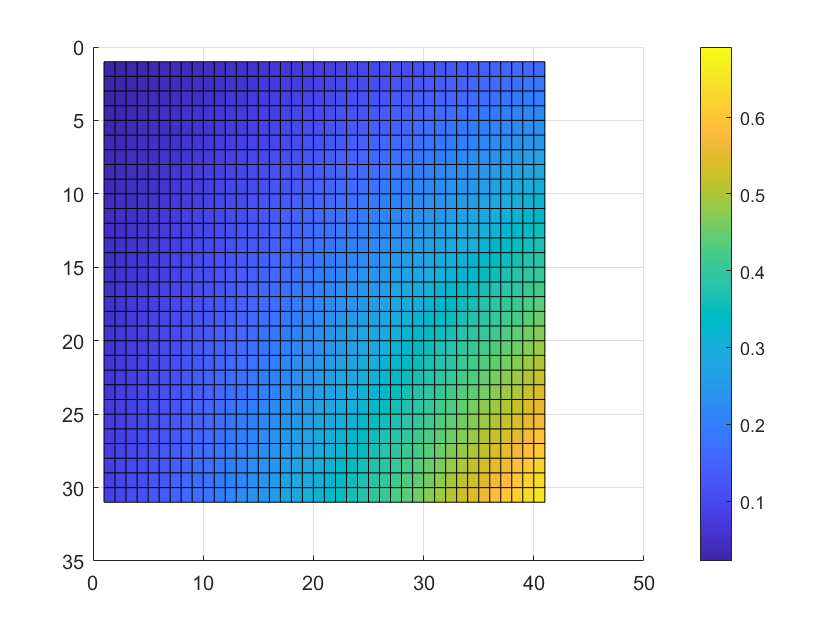

surf(V_matrix)
view([90,90])
colorbar

min_V=min(min(V_matrix))

min_V = 0.0220

[irow jcol]= find(V_matrix ==min_V) %it gives the linear index

irow = 1

jcol = 1

r_min_V=r(irow)

r_min_V = 0.0400

l_min_V=l(jcol)

l_min_V = 10

## Before Q3

r_min_Rth

r_min_Rth = 0.0700

r_min_V

r_min_V = 0.0400

l_min_Rth

l_min_Rth = 40

l_min_V

l_min_V = 10

lambda=0.5; %lambda is with V

r_temp=r_min_V:step_r: r_min_Rth;
l_temp=l_min_V:step_l:l_min_Rth;
% they must be the same size. Fortunatly they are.
Rth_table= 1./(2*pi*h.*r_temp.*l_temp)+log(r_temp/ri)./(2*pi*k.*l_temp);
V_table=pi.*(r_temp.^2-ri^2).*l_temp;
choice=1:length(V_table); %creat a choice table
choiceTable=[choice;Rth_table;V_table;r_temp;l_temp];
choiceTable=choiceTable';
% scale the Rth and V of choiceTable
% scale Rth
choiceTable(:,2)=(choiceTable(:,2)-min(choiceTable(:,2)))/(max(choiceTable(:,2))-min(choiceTable(:,2)));
% scale V
choiceTable(:,3)=(choiceTable(:,3)-min(choiceTable(:,3)))/(max(choiceTable(:,3))-min(choiceTable(:,3)));

result=zeros(8,3);
for lambda=0.1:0.1:0.8
% compute WS
WS=choiceTable(:,2)*(1-lambda)+lambda*choiceTable(:,3); %weighted sum
% paste WS into choiceTable
choiceTable=[choiceTable WS]; %put the weighted sum into the choice table
% find the min WS
[r1,l1,minWS1]=grant(lambda, choiceTable);
result(round(lambda*10),:)=[r1,l1,minWS1];  % !!!!!!!!!!!!!!!!! any solution not to use unit64
end
result

result =     0.0700   40.0000    0.1000
    0.0700   40.0000    0.1000
    0.0700   40.0000    0.1000
    0.0700   40.0000    0.1000
    0.0700   40.0000    0.1000
    0.0700   40.0000    0.1000
    0.0700   40.0000    0.1000
    0.0700   40.0000    0.1000


## test

 lambda=0.1:0.1:0.8

lambda =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000


## Q3 phase 1 

figure(1)
hold on
for i=1:length(r_temp)
    for j=1:length(l_temp)
        plot(r_temp(i),l_temp(j),'o');
    end
end

## Q3 phase 2

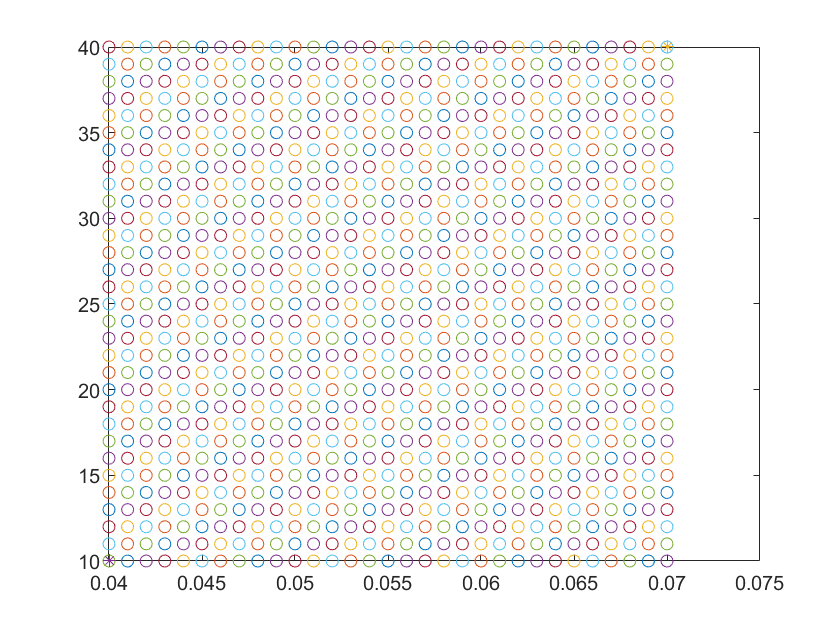

plot(r_min_Rth,l_min_Rth,'x')
hold on
plot(r_min_V,l_min_V,'x')

hold off

## Q4 Objective space

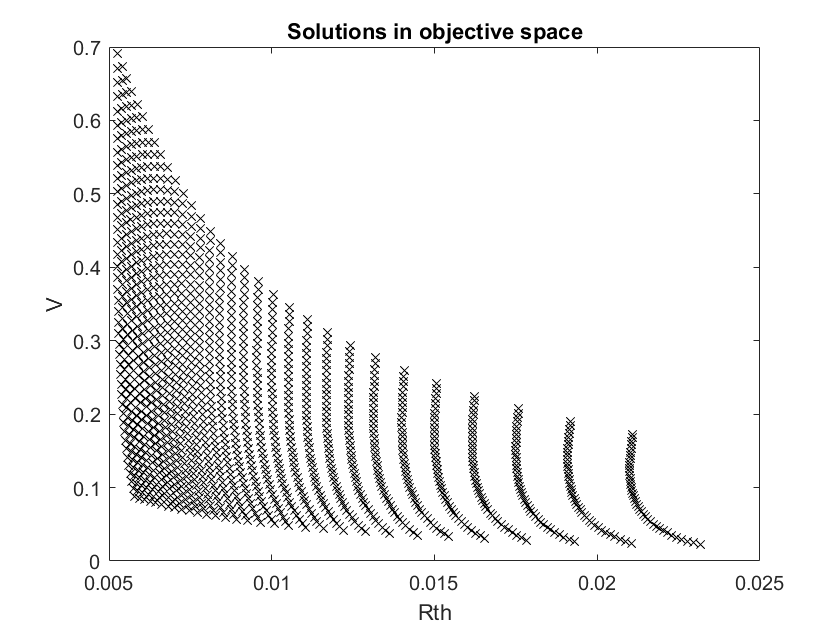

figure(4)
hold on
plot(Rth_matrix,V_matrix,'kx')
title('Solutions in objective space')
xlabel('Rth')
ylabel('V')

## fct

function [r,l,minWS] = grant(lambda,choiceTable)
%grant ; give the set of r and l when WS is minimum
%   Detailed explanation goes here
    minWS=min(choiceTable(:,6)); %min WS
    [ilig icol]=find(choiceTable==minWS); %just need ilig, icol is 6
    r=choiceTable(ilig,4);
    l=choiceTable(ilig, 5);
end